# **Obtener los datos del archivo .csv**

data = readmatrix("../Data/150_120_CQRobot.csv");

t = data(:,1); %tiempo
u = data(:,2); %señal de referencia
y = data(:,3); %señal de salida

Ts = mean(diff(t));

# **Gráfica de la salida del sistema**

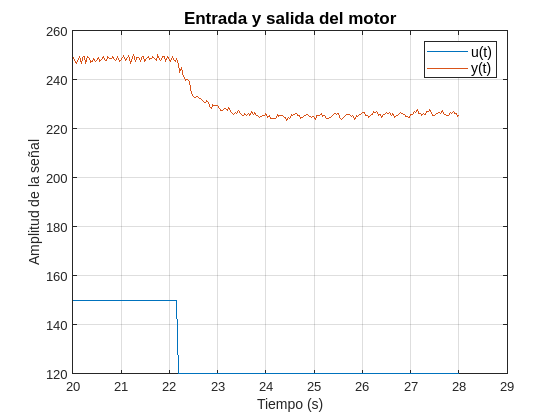

figure(1);
plot(t,u,t,y,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)', 'y(t)','FontSize',11);
title('Entrada y salida del motor', 'FontSize',13);
grid on;

# **Eliminar el DC Offset**


porcentaje_inicial = 0.10; % Se toma un aproximado de qué porcentaje de la respuesta 
num_puntos = length(y);
puntos_iniciales = round(porcentaje_inicial * num_puntos);
dc_offset_u = mean(u(1:puntos_iniciales));
dc_offset_y = mean(y(1:puntos_iniciales));

u_sindc = u - dc_offset_u;
y_sindc = y - dc_offset_y;

# **Gráfica de la salida sin el DC Offset**

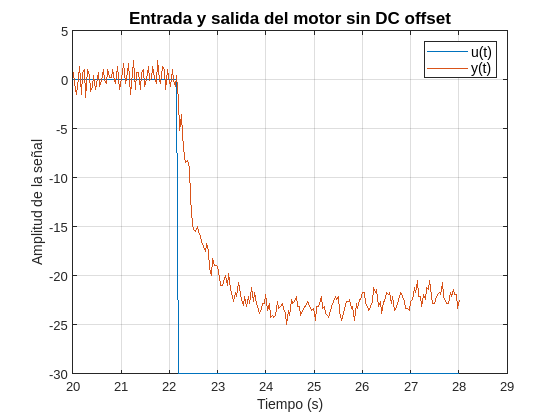

figure(2);
plot(t, u_sindc, t, y_sindc, 'LineWidth',1.1);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# **Abrir el System Identification Toolbox**

systemIdentification();

Se puede cargar el valor de la planta ya calculada con un 90.84% de precisión dándole click al modelo_primer_orden.mat

# ** Datos necesarios para el método de Alfaro**

porcentaje_final = 0.10; % Se toma un aproximado de donde la respuesta tiene su valor final
num_puntos = length(y);
puntos_final = round(porcentaje_final * num_puntos);
y_final = y_sindc(end-puntos_final+1:end);
promedio_yfinal = mean(y_final);

% Calcular y_inicial 
puntos_iniciales = round(0.10 * num_puntos);
y_inicial = mean(y_sindc(1:puntos_iniciales));

% Encontrar cambio_esc
cambio_esc = find(u_sindc < 0, 1);

deltau = u(1) - u(cambio_esc);

deltay = y_inicial - promedio_yfinal;

deltay25 = y_inicial - 0.25 * deltay;
deltay75 = y_inicial - 0.75 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t25
todos_t25 = find(y_sindc(cambio_esc:end) <= deltay25);
pos_t25 = todos_t25(min(3, end)) + cambio_esc - 1;

% Para t75
todos_t75 = find(y_sindc(cambio_esc:end) <= deltay75);
pos_t75 = todos_t75(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t25_tot = t(pos_t25);
t75_tot = t(pos_t75);
tcambio = t(cambio_esc);

% Se resta el tiempo antes de hacer el cambio escalón
t25 = t25_tot - tcambio;
t75 = t75_tot - tcambio;

# Método de PDMTM Alfaro (método de 2 puntos)

a = 0.5776

a = 0.5776

b = 1.5552

b = 1.5552

K = deltay / deltau;
T = a*(t75 - t25);
%No se calcula L ya que la planta no tiene tiempo muerto

# Gráfica con el método de Alfaro

s = tf('s');
t1 = (20:0.0370:29)'

t1 =    20.0000
   20.0370
   20.0740
   20.1110
   20.1480
   20.1850
   20.2220
   20.2590
   20.2960
   20.3330


P1 = K / (T*s + 1)^2


P1 =
 
            0.7339
  --------------------------
  0.04378 s^2 + 0.4185 s + 1
 
Continuous-time transfer function.
Model Properties


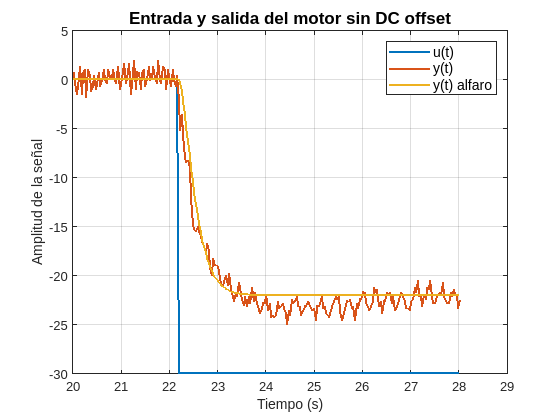

[y_sim1, t_sim] = lsim (P1, u_sindc, t1);
figure(3);

plot(t, u_sindc, t, y_sindc, t, y_sim1, 'LineWidth',1.5);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'y(t) alfaro','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;